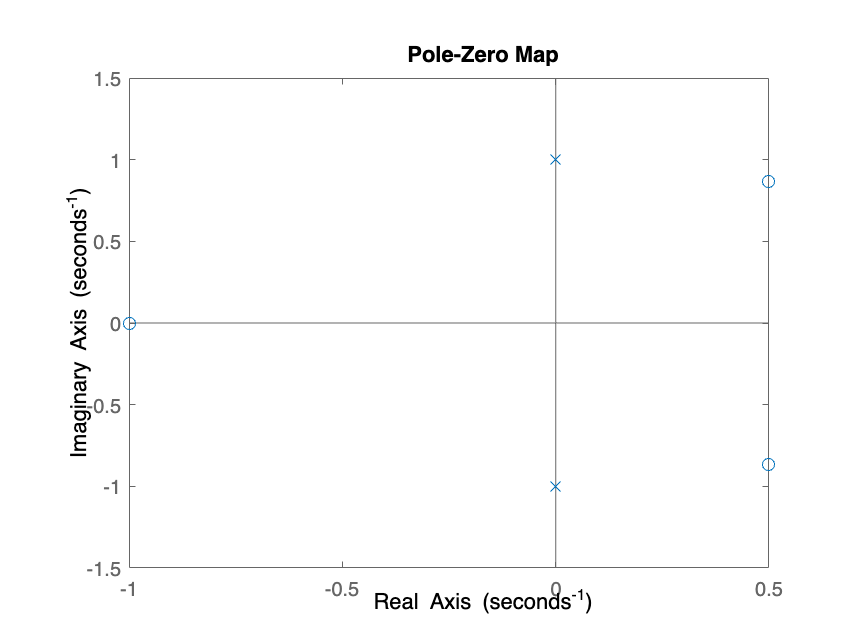

%6.67a
z=roots([1,0,0,1]);
p=roots([1,0,2,0,1]);
k=1;
syszpk=zpk(z,p,k);
systf=tf(syszpk);
pzmap(systf);

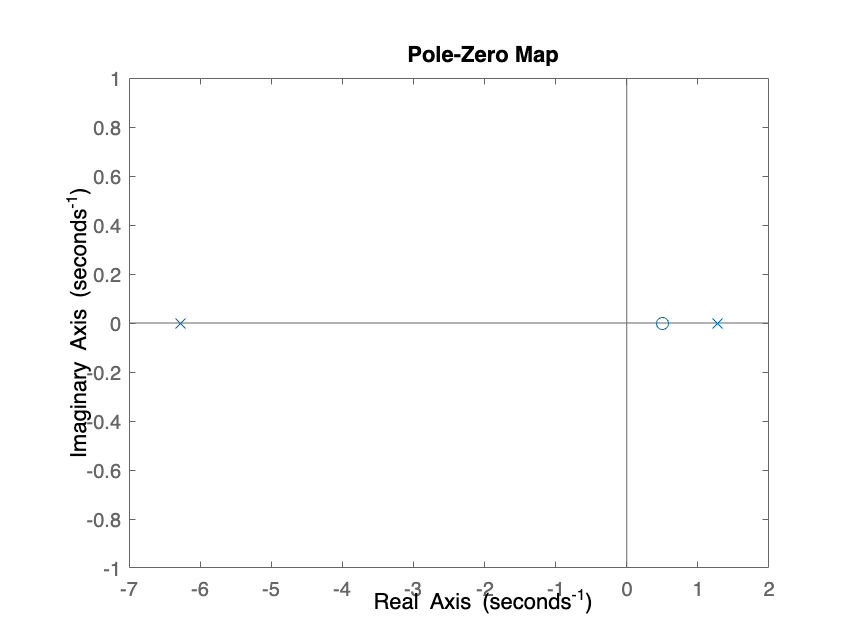

%6.67b
A=[1,2;1,-6];
b=[1;2];
c=[0,1];
D=[0];
pzmap(ss(A,b,c,D));

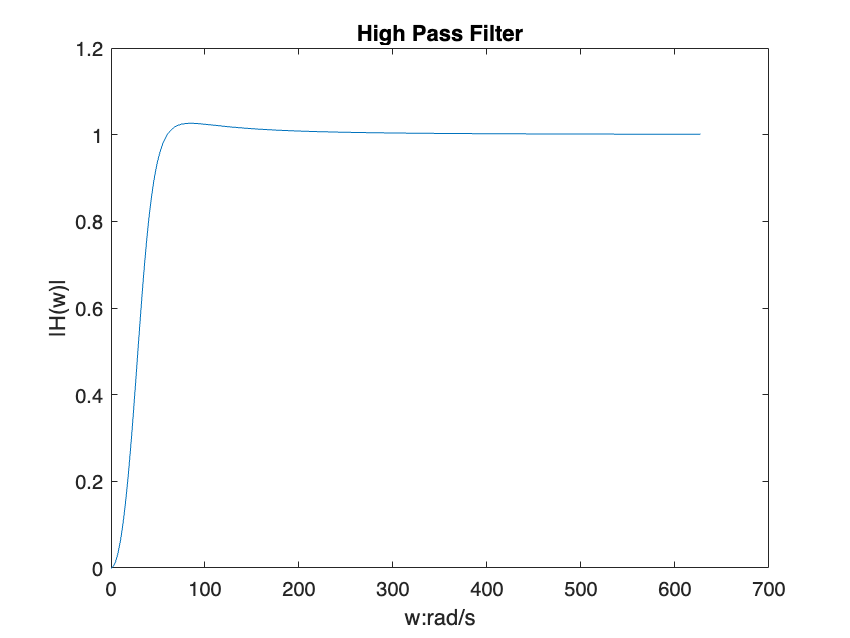

%6.70a
z=[0,0];
k=1;
p=[25+j*10*pi,25-j*10*pi];
syszpk=zpk(z,p,k);
systf=tf(syszpk); %convert to transfer function form
w=[0:499]*200*pi/500; %Frequencies from 0 to 628 rad/s
H=freqresp(systf,w);
Hmag=abs(squeeze(H));
plot(w,Hmag);
title('High Pass Filter');
xlabel('w:rad/s');
ylabel('|H(w)|');

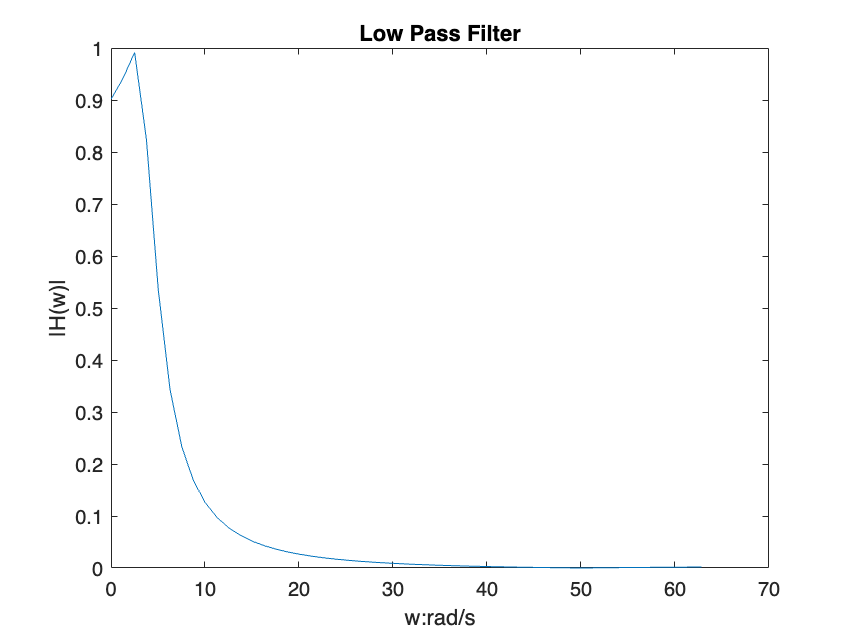

%6.70b
z=[j*50,-j*50];
k=0.005;
p=[2+j*pi,2-j*pi];
syszpk=zpk(z,p,k); 
systf=tf(syszpk); %convert to transfer function form
w=[0:50]*200*pi/500; %Frequencies from 0 to 62.8 rad/s
H=freqresp(systf,w);
Hmag=abs(squeeze(H));
plot(w,Hmag);
title('Low Pass Filter');
xlabel('w:rad/s');
ylabel('|H(w)|');

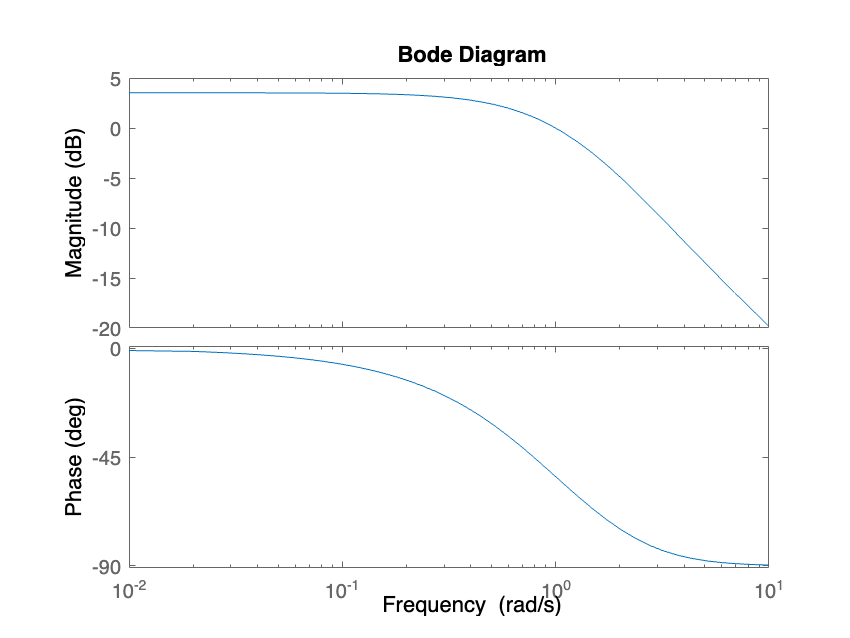

%6.73bi
A=[-1,1;0,-2];
B=[3;-1];
C=[1,2];
D=[0];
[b,a] = ss2tf(A,B,C,D);
sys=tf(b,a);
bode(sys);

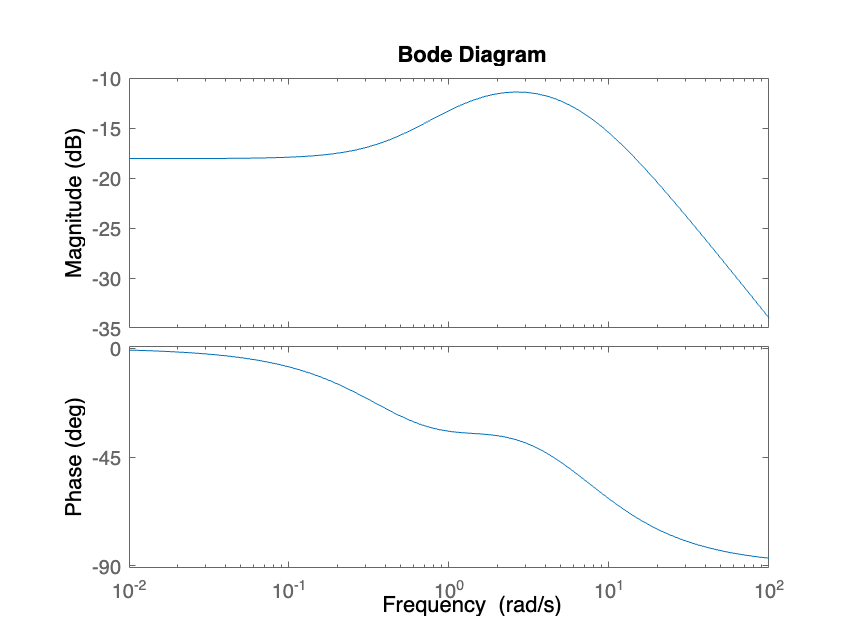

%6.73bii
A=[1,2;1,-6];
B=[1;2];
C=[0,1];
D=[0];
[b,a] = ss2tf(A,B,C,D);
sys=tf(b,a);
bode(sys);